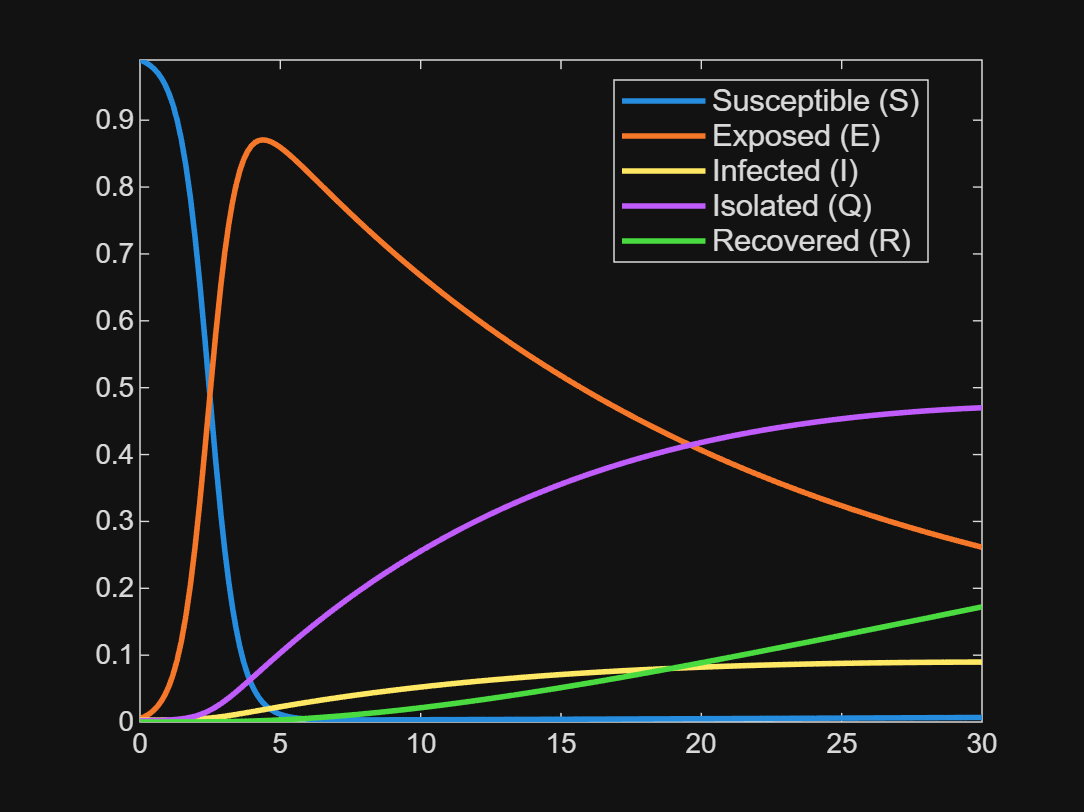

% This code creates a graphical representation of a normalized
% SEIQR model based on the given parameters

clear; clc; close all;

% define parameters
A = 0.5;             % birth rate
mu = 0.005;         % death rate
beta = 0.020;        % transmission rate
pi_ = 0.009;         % rate exposed -> infected
gamma = 0.045;       % rate exposed -> isolated
sigma = 0.020;      % rate infected -> isolated
theta = 0.020;      % recovery rate from isolation
N_eq = A/mu;       % equilibrium population size


% intial values (absolute)
S_t0 = 0.99*N_eq; % Suseptible 
E_t0 = 0.005*N_eq; % Exposed
I_t0 = 0.003*N_eq; % Infected
Q_t0 = 0.002*N_eq; % Isolated
R_t0 = 0; % Recovered
t0 = 0;

% normalize initial conditions
s0 = S_t0 / N_eq;
e0 = E_t0 / N_eq;
i0 = I_t0 / N_eq;
q0 = Q_t0 / N_eq;
r0 = R_t0 / N_eq;
initial_conditions = [s0, e0, i0, q0, r0];

t_end = [t0, 30]; % time frame evaluated

% solve SEIQR
[t1, y1] = ode45(@(t, y) SEIQR_func_norm(mu, beta, pi_, gamma, sigma, theta, y, N_eq), t_end, initial_conditions);


% Normalized susceptible population over time
figure;
plot(t1,y1(:,1),'LineWidth', 2) % Infected
hold on;
plot(t1,y1(:,2),'LineWidth', 2) % Isolated
plot(t1,y1(:,3),'LineWidth', 2) % Exposed
plot(t1,y1(:,4),'LineWidth', 2) % Infected
plot(t1,y1(:,5),'LineWidth', 2) % Infected
ylim([0, inf]);
xlim([0, inf]);
legend({'Susceptible (S)','Exposed (E)', 'Infected (I)','Isolated (Q)', 'Recovered (R)'}, ...
       'Location', 'best', 'FontSize', 11)
hold off


% load in actual cases per day to use to evaluate MAE
cases_per_day_path = '/MATLAB Drive/MAT292 Project/cases_per_day_2020_2023.csv';

daily_cases = load_cases_from_csv(cases_per_day_path);
CS_testing = create_CS(daily_cases, t_end(2));

DR_vals = zeros(length(t1), 1); 
for i = 1:length(t1)
    I = y1(i, 3); 
    DR_vals(i) = I;
end

[mae, errors, y1_discrete] = calculate_mae(t_end(1), t_end(2), CS_testing, t1, DR_vals);

MAE Calculation Summary:
  Data points: 31
  MAE: 11376.814493
  Range of actual data: [1001.5000, 25779.5714]
  Range of solver data: [0.0030, 0.0897]


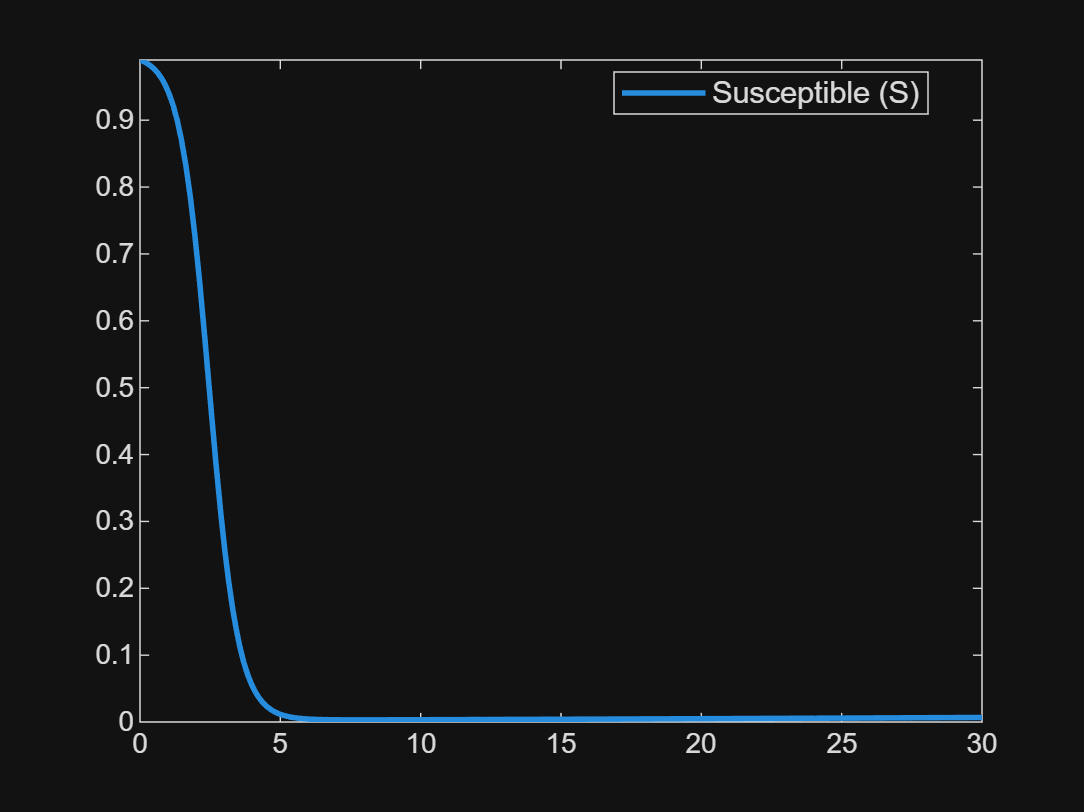


% Graph of susceptible population only
figure;
plot(t1,y1(:,1),'LineWidth', 2) % Infected
ylim([0, inf]);
xlim([0, 30]);
legend('Susceptible (S)','Location', 'best', 'FontSize', 11)

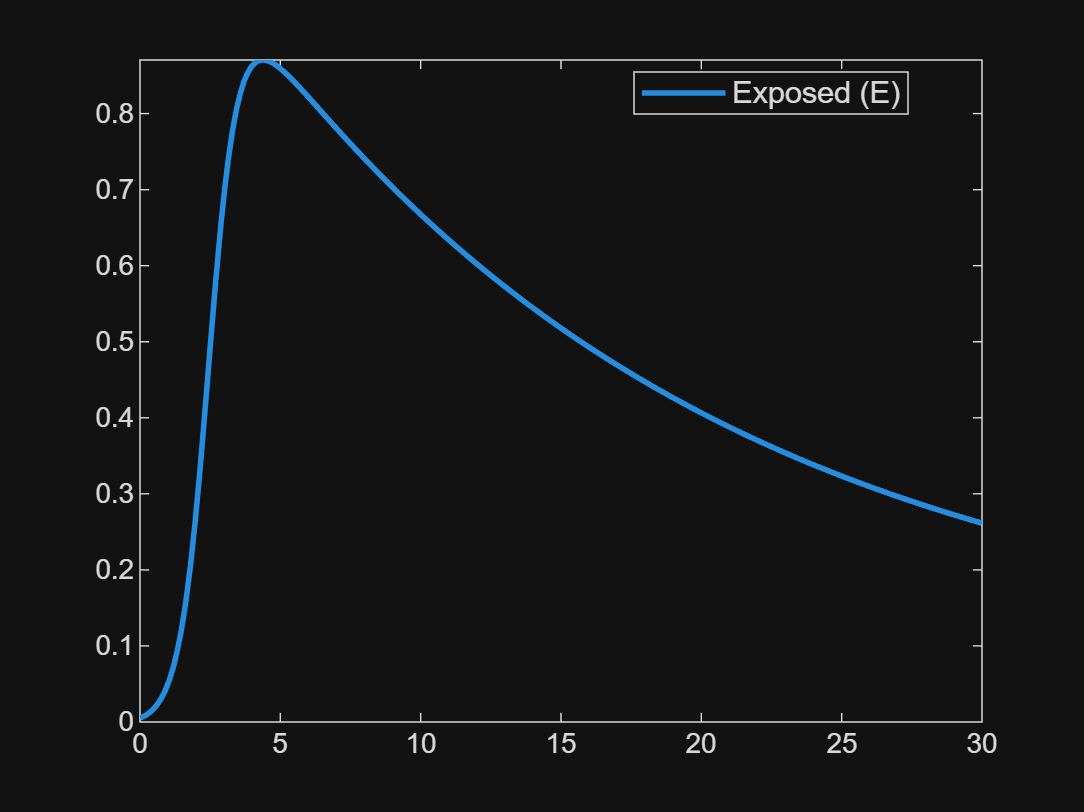


% Graph of exposed population only
figure;
plot(t1,y1(:,2),'LineWidth', 2) % Infected
ylim([0, inf]);
xlim([0, 30]);
legend('Exposed (E)','Location', 'best', 'FontSize', 11)

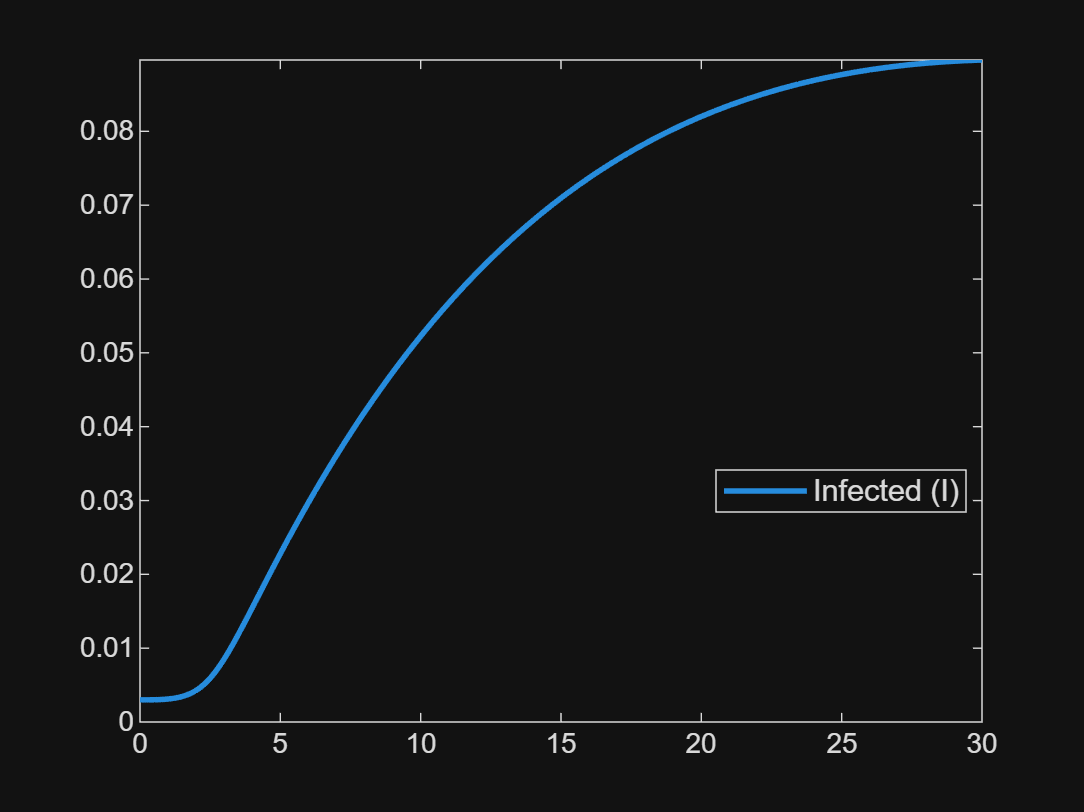


% Graph of infected population only
figure;
plot(t1,y1(:,3),'LineWidth', 2) % Infected
ylim([0, inf]);
xlim([0, 30]);
legend('Infected (I)','Location', 'best', 'FontSize', 11)

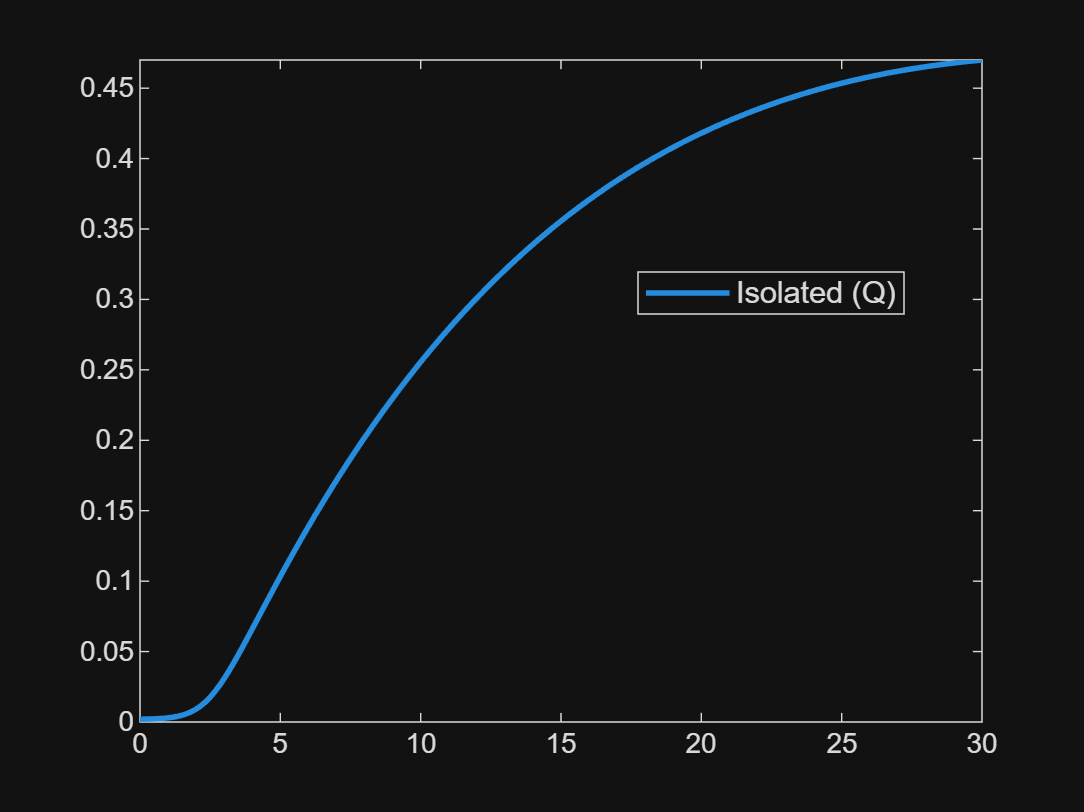


% Graph of isolated population only
figure;
plot(t1,y1(:,4),'LineWidth', 2) % Infected
ylim([0, inf]);
xlim([0, 30]);
legend('Isolated (Q)','Location', 'best', 'FontSize', 11)

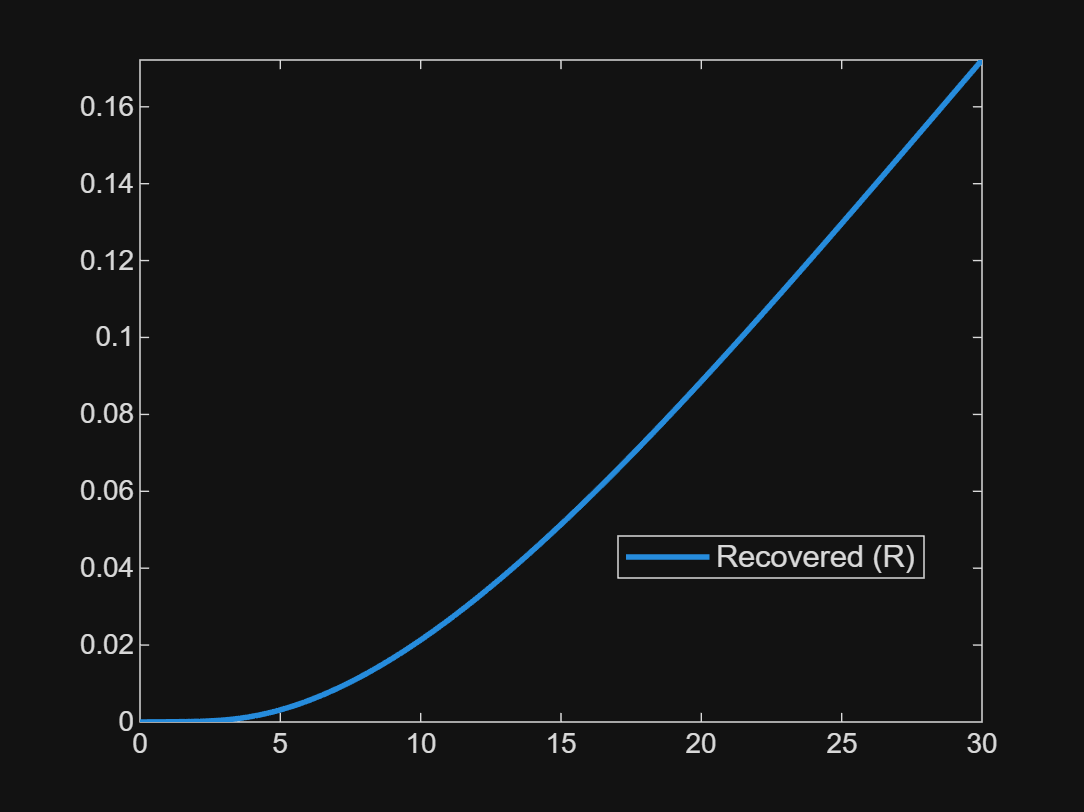



% Graph of recoved population only
figure;
plot(t1,y1(:,5),'LineWidth', 2) % Infected
ylim([0, inf]);
xlim([0, 30]);
legend('Recovered (R)','Location', 'best', 'FontSize', 11)


%implementaion of SEIQR model relationships
function dydt = SEIQR_func_norm(mu, beta, pi_, gamma, sigma, theta, y, N_eq)
    s = y(1);
    e = y(2);
    i = y(3);
    q = y(4);
    r = y(5);

    dsdt = mu*(1 - s) - beta*s*N_eq*(e + i);
    dedt = beta*N_eq*s*(e + i) - pi_*e - (mu + gamma)*e;
    didt = pi_*e - sigma*i - mu*i;
    dqdt = gamma*e + sigma*i - theta*q - mu*q;
    drdt = theta*q - mu*r;
    dydt = [dsdt; dedt; didt; dqdt; drdt];
end

mae

function [mae, errors, y1_discrete] = calculate_mae(t0, t_end, CS, t_solver, y_solver)
%compare spline daily cases of actual cases (7 day rolling average) vs ode
%prediction

    %get discrete points
    t_discrete = t0:1:t_end;

    CS_discrete = ppval(CS, t_discrete);
    % CS_discrete = CS_discrete(1,:);
    % disp(CS_discrete)
    CS_discrete = CS_discrete(:);
    
    y1_discrete = interp1(t_solver, y_solver, t_discrete, 'linear', 'extrap');
    y1_discrete = y1_discrete(:); %make same orientation

    errors = abs(CS_discrete - y1_discrete);
    mae = mean(errors);
    
    % Display summary
    fprintf('MAE Calculation Summary:\n');
    fprintf('  Data points: %d\n', length(t_discrete));
    fprintf('  MAE: %.6f\n', mae);
    fprintf('  Range of actual data: [%.4f, %.4f]\n', min(CS_discrete), max(CS_discrete));
    fprintf('  Range of solver data: [%.4f, %.4f]\n', min(y1_discrete), max(y1_discrete));
end

function CS = create_CS(daily_cases, t_end) % create splines of daily cases
    weekly_avg = movmean(daily_cases, 7);
    weekly_avg = weekly_avg(1:t_end);
    t_integer = 1:length(weekly_avg);
    CS = spline(t_integer, weekly_avg);
end

function daily_cases = load_cases_from_csv(filename)
    data = readtable(filename, 'Delimiter', ',');
    daily_cases = data{:, 2};
end